# Práctica 3: Ecualización de una señal QAM-16 transmitida por un canal multitrayectoria

**Autores:** Pedro Ángel Estepa García, Daniela Arechúa Batalla

**Asignatura:** Procesado avanzado de señal en comunicaciones

**Titulación:** Master Universitario en Ingeniería de Telecomunicación

**Fecha de entrega: **

## 1. Fundamentos

En un sistema de comunicacion se transmiten símbolos sk de una constelacion QAM-16 a través de un canal multipath con un periodo de símbolo T. La constelacion y el mapeo (tipo Gray) de los cuartetos de bits en la misma es el siguiente: 

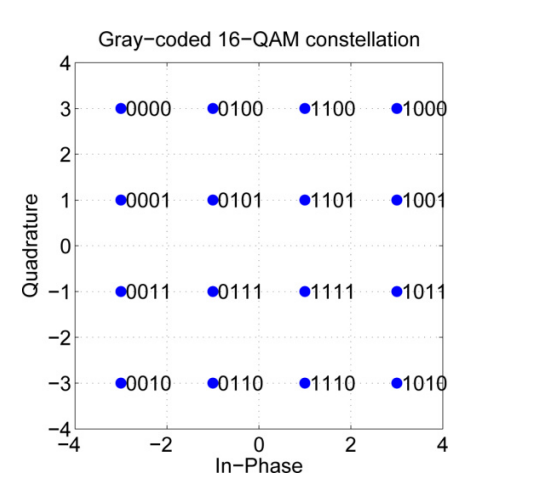

La secuencia de símbolos QAM-16 es obtenida a partir de una señal de audio muestreada a calidad telefonica (8-bits, 8 KHz, 64 kbps). En concreto, la secuencia de símbolos se compone (por este orden) de 100 símbolos aleatorios iniciales, 300 símbolos de entrenamiento y los símbolos correspondientes a las muestras de audio, a las que se les ha aplicado un offset de 128 para obtener un rango de senal de [0,255]. Para cada muestra se transmiten primero los 4 LSB bits y a continuacion los 4 MSB bits. 

El modelo de transmision en banda base es el siguiente:

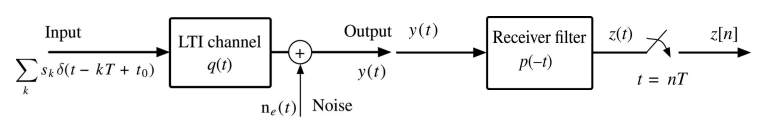

El canal total a ecualizar es $h\left(t\right)=q\left(t\right)*p\left(-t\right)$  incluye el pulso p(t) (tipo coseno remontado), el canal físico multitrayectoria y el filtro de receptor p(−t). Ademas, el canal introduce ruido aditivo blanco gaussiano. El objetivo de esta practica es ecualizar la señal z(n) recibida del canal total mediante un ecualizador tipo FIR de 9 coeficientes (M = 8). Se trabajara sobre el modelo de transmisión en banda base y discreto (con periodo de símbolo T = 1/16 ms) de la siguiente figura: 

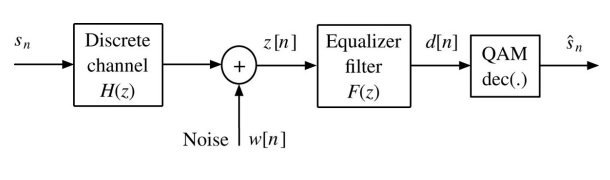

## 2. Realización práctica

### 2.1 Primer caso

Ecualizador para canal fijo con ruido AWGN con SNR por bit Eb/N = 22 dB. Se diseñará un ecualizador fijo tipo TSE-LS a partir de la secuencia de entrenamiento. Para la realizacion de este apartado se dispone del fichero Tx_fijo_variables.mat, que contiene las siguientes variables:

- x: senal de audio original (formato double, sin offset, rango [−128,127]).

- trainseq: secuencia de 300 símbolos complejos de entrenamiento.

- z: señal de salida (compleja) del canal total (incluyendo secuencia de entrenamiento). Esta señal se ha obtenido por muestreo al symbol-rate de la señal recibida y se le han compensado los retardos introducidos en la transmision, por lo que está sincronizada con la secuencia originalmente transmitida.

Se determinara la influencia de la introducción de un retardo u en la decision

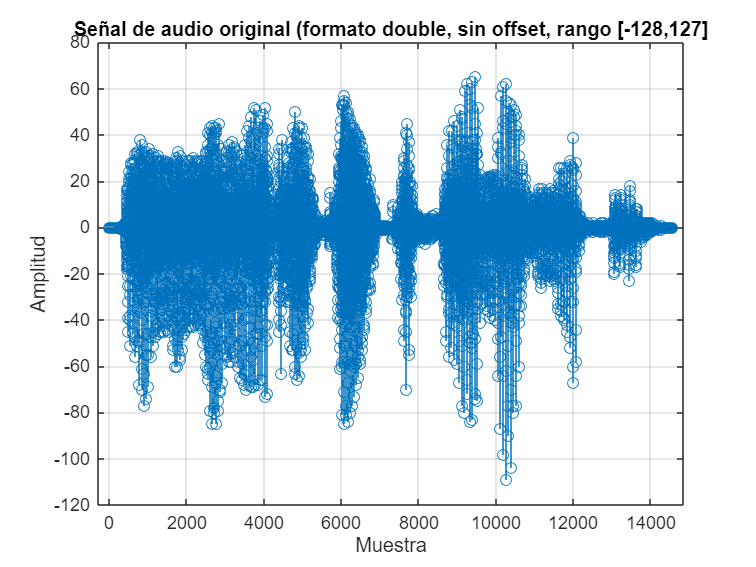

% Parametros
R = 62.5; % Symbol rate 1/T = 1/16ms
sps = 8; % Samples per symbol (Factor sobremuestreo M)

% Cargamos el fichero
load 'Tx_fijo_variables.mat' % carga secuencia recibida sobremuestreada M=8.

rx = x;
stem(rx) 
title('Señal de audio original (formato double, sin offset, rango [-128,127]')
ylabel('Amplitud');xlabel('Muestra');
grid on;

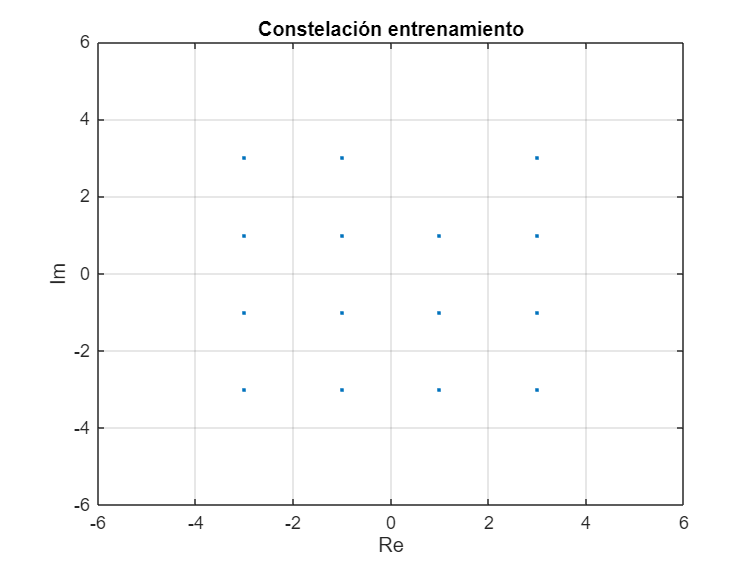

rtrainseq = trainseq;
plot(rtrainseq(1:sps:end),'.')
axis([-6 6 -6 6])
title('Constelación entrenamiento')
xlabel('Re')
ylabel('Im')
grid on

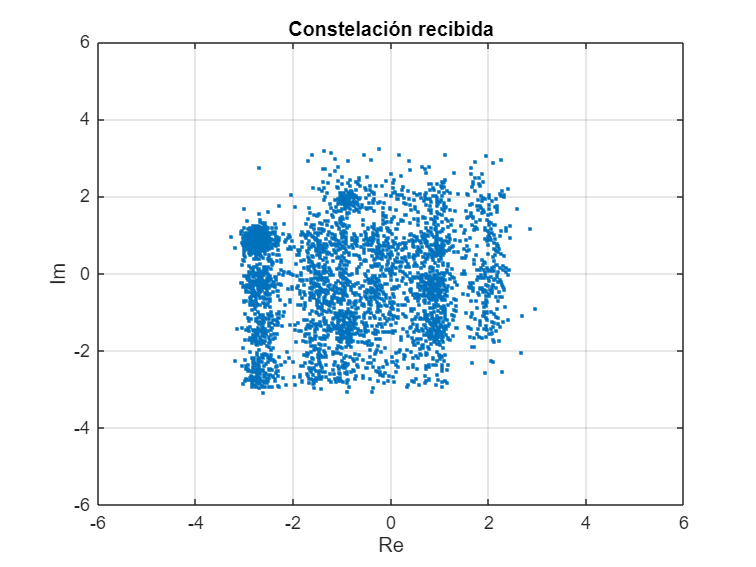

rz = z;
figure;
plot(rz(1:sps:end),'.')
axis([-6 6 -6 6])
title('Constelación recibida')
xlabel('Re')
ylabel('Im')
grid on

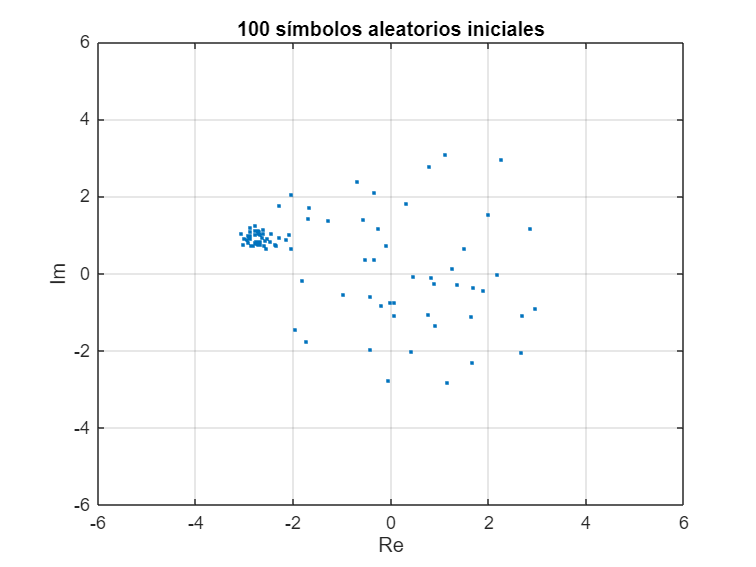

figure;
plot(rz(1:sps:100*sps),'.')
axis([-6 6 -6 6])
title('100 símbolos aleatorios iniciales')
xlabel('Re')
ylabel('Im')
grid on

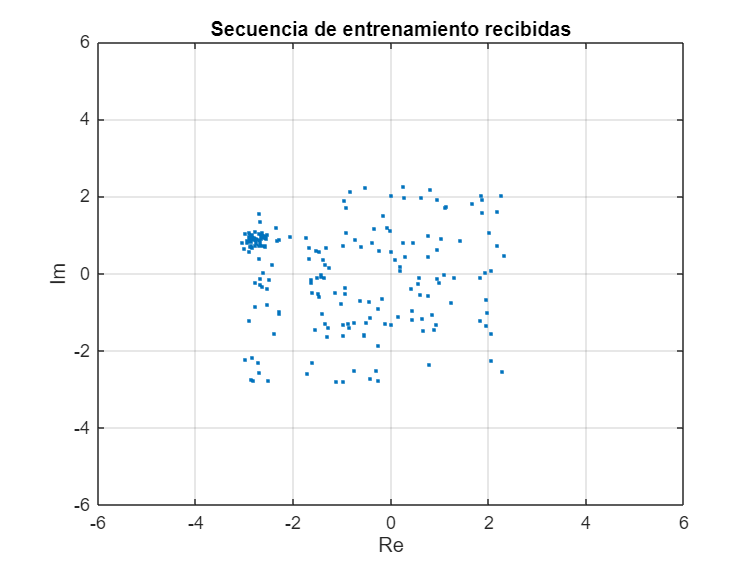

figure;
plot(rz(100*sps+1:sps:300*sps),'.')
axis([-6 6 -6 6])
title('Secuencia de entrenamiento recibidas')
xlabel('Re')
ylabel('Im')
grid on

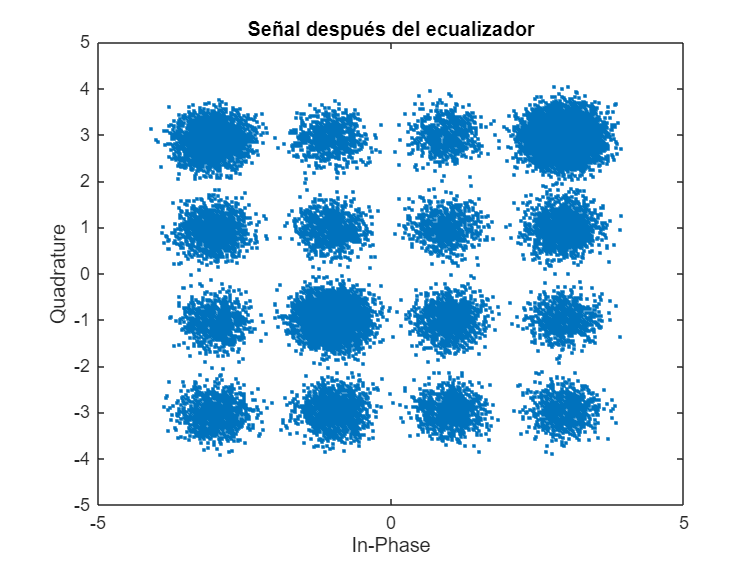

% Definir parámetros
N = length(trainseq); % Número de símbolos de entrenamiento
L = 8; % Orden del filtro FIR
ini = 101; % Inicio de la señal (entrenamiento + mensaje)
u = 2; % Retardo 
       % Dicho retardo es con el que se obtiene mayor SNR y menor SER
       
% Construcción de la matriz z para el ecualizador
Z = zeros(N, L+1);
for i = 1:N
    for j = 1 : L+1  
        Z(i, j) = z(i-j+ini+u); 
    end
end

% Cálculo de los coeficientes del ecualizador
f = (Z' * Z)\(Z' * trainseq);

% Aplicar el filtro FIR a la señal recibida
d = zeros(length(z), 1);
N_z = length(z); % Tamaño señal recibida
for n = L+1:N_z
    d(n) = sum(f .* z(n:-1:n-L));  % Convolución  
end

% Nos quedamos con la señal mensaje (quitamos secuencia aleatoria y
% secuencia entrenamiento)
d = d(ini+N:end);

% Representación de la señal tras el ecualizador
figure;
plot(real(d), imag(d), '.');
xlabel('In-Phase');
ylabel('Quadrature');
title('Señal después del ecualizador');
xlim([-5 5]);
ylim([-5 5]);

% Demodulación de la señal ecualizada
d_demod = qamdemod(d, 16);

% Conversión de los símbolos QAM a audio
d_muestras = qam16_to_audio8bit(d_demod);

%% EVALUACIÓN DEL RENDIMIENTO

% Alinear d_muestras con x automáticamente
[muestras_aligned, x_aligned] = alignsignals(d_muestras, x);

% Recortar a la longitud mínima después de la alineación
min_len = min(length(x_aligned), length(muestras_aligned));
x_aligned = x_aligned(1:min_len);
muestras_aligned = muestras_aligned(1:min_len);

% Cálculo SNR
snr_audio = 10 * log10(sum(x_aligned.^2) / sum((muestras_aligned - x_aligned).^2));

% Cálculo de SER (Symbol Error Rate)
x_simb = audio8bit_to_qam16(x); % Convertir la señal original a símbolos QAM
[d_demod_aligned, x_simb_aligned] = alignsignals(d_demod, x_simb);
min_len = min(length(x_simb_aligned), length(d_demod_aligned));
x_simb_aligned = x_simb_aligned(1:min_len);
d_demod_aligned = d_demod_aligned(1:min_len);
[errores, ratio] = symerr(x_simb_aligned, d_demod_aligned); % Calcular los errores de símbolo
SER = ratio * 100; % Convertir a porcentaje

% Mostrar resultados
fprintf('SNR Audio: %.2f dB\n', snr_audio);

SNR Audio: 21.26 dB


fprintf('SER: %.2f%%\n', SER);

SER: 0.08%



% Reproducción de audio
soundsc(x, 8e3); % Señal original transmisita
pause(3);
soundsc(d_muestras, 8e3); % Señal obtenida tras la ecualización


### 2.2. Segundo caso

Ecualizador TSE decision-directed para canal variable con ruido AWGN (SNR por bit Eb/N = 22 dB). El ecualizador inicial se obtendra mediante LS a partir de la secuencia de entrenamiento. Se comprobará el funcionamiento del algoritmo adaptable NLMS y se comparará con el ecualizador LS fijo. Para la realizacion de este apartado se dispone del fichero Tx_var_variables.mat, que contiene las mismas variables que en el apartado anterior. Se determinara la influencia de la introducción de un retardo u en la decisión. 

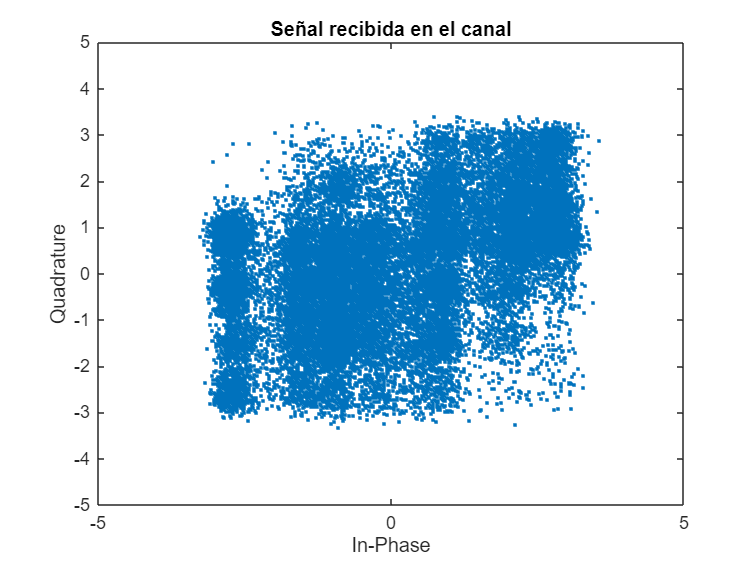


%% PARTE 2: ECUALIZADOR TSE DECISION-DIRECTED PARA CANAL VARIABLE

% CARGAR VARIABLES
%   x: señal de audio original
%   trainseq: secuencia de entrenamiento
%   z: señal salida del canal total
load 'Tx_var_variables.mat';

% Representación de la constelación recibida
figure(1);
plot(real(z), imag(z), '.');
xlabel('In-Phase');
ylabel('Quadrature');
title('Señal recibida en el canal');
xlim([-5 5]);
ylim([-5 5]);

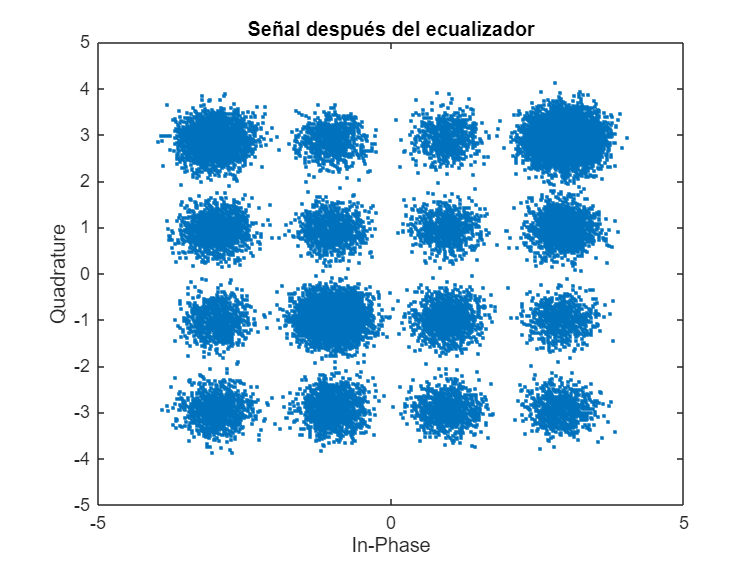

% Definir parámetros
N = length(trainseq); % Número de símbolos de entrenamiento
L = 8; % Orden del filtro FIR
ini = 101; % Inicio de la señal (entrenamiento + mensaje)
u = 2; % Retardo 
v = 0.01; % Paso de adaptación NLMS
          % Este valor es con el que se obtiene mayor SNR y menor SER

%% CÁLCULO DEL ECUALIZADOR INICIAL
% Construcción de la matriz z para el ecualizador inicial
Z = zeros(N, L+1);
for i = 1:N
    for j = 1 : L+1  
        Z(i, j) = z(i-j+ini+u); 
    end
end

% Cálculo inicial de los coeficientes del ecualizador inicial
f = (Z' * Z)\(Z' * trainseq);

% Aplicar el filtro FIR a la señal recibida
d = zeros(length(z), 1);
N_z = length(z); % Tamaño señal recibida
for n = L+1:N_z
    d(n) = sum(f .* z(n:-1:n-L));  % Convolución  
end
ini_mensaje = 401;  % Comenzamos en la muestra n = 401 que es donde empieza el mensaje
d_ini = d(401); % Primer símbolo de salida del ecualizador

%% ECUALIZADOR ADAPTABLE --> ALGORITMO NLMS

z_n = z(ini_mensaje:-1:ini_mensaje - L); % Ventana inicial
f_adap = f; % Coeficientes del filtro ecualizador iniciales
d = zeros(N_z - ini_mensaje, 1); % Señal deseada

for n = 1 : (N_z - ini_mensaje) % Bucle para simular el filtro adaptable

    % Ventana vector z
    z_n = z(ini_mensaje + n: -1 : ini_mensaje + n - L);
    
    % Filtrado FIR
    d(n) = sum(f_adap .* z_n);  % Convolución

    % Cálculo error
    e(n) = qammod(qamdemod(d(n),16),16) - d(n);

    % Adaptación
    f_adap = f_adap + (v/(z_n' * z_n) * e(n)) .* conj(z_n);


end

% La salida del ecualizador es la concatenación de la salida del
% ecualizador inicial con el resto de salidas del ecualizador adaptable
d_final = [d_ini; d]; 

% Representación de la señal tras el ecualizador
figure;
plot(real(d_final), imag(d_final), '.');
xlabel('In-Phase');
ylabel('Quadrature');
title('Señal después del ecualizador');
xlim([-5 5]);
ylim([-5 5]);

% Demodulación de la señal ecualizada
d_demod = qamdemod(d_final, 16);

% Conversión de los símbolos QAM a audio
d_muestras = qam16_to_audio8bit(d_demod);

%% EVALUACIÓN DEL RENDIMIENTO

% Alinear d_muestras con x automáticamente
[muestras_aligned, x_aligned] = alignsignals(d_muestras, x);

% Recortar a la longitud mínima después de la alineación
min_len = min(length(x_aligned), length(muestras_aligned));
x_aligned = x_aligned(1:min_len);
muestras_aligned = muestras_aligned(1:min_len);

% Cálculo SNR
snr_audio = 10 * log10(sum(x_aligned.^2) / sum((muestras_aligned - x_aligned).^2));

% Cálculo SER (Symbol Error Rate)
x_simb = audio8bit_to_qam16(x); % Convertir la señal original a símbolos QAM
[d_demod_aligned, x_simb_aligned] = alignsignals(d_demod, x_simb);
min_len = min(length(x_simb_aligned), length(d_demod_aligned));
x_simb_aligned = x_simb_aligned(1:min_len);
d_demod_aligned = d_demod_aligned(1:min_len);
[errores, ratio] = symerr(x_simb_aligned, d_demod_aligned); % Calcular los errores de símbolo
SER = ratio * 100; % Convertir a porcentaje

% Mostrar resultados
fprintf('SNR Audio: %.2f dB\n', snr_audio);

SNR Audio: 23.75 dB


fprintf('SER: %.2f%%\n', SER);

SER: 0.11%


% Reproducción de audio
soundsc(x, 8e3); % Señal original transmisita
pause(3);
soundsc(d_muestras, 8e3); % Señal obtenida tras la ecualización

% Se obtiene mejor resultado (mayor SNR) con el filtro adaptable ya que el
% algoritmo NLMS ajusta los coeficientes en cada iteración adaptándose a
% los cambios en el canal mientras que el filtro fijo únicamente minimiza
% el error para la fase de entrenamiento. 
